# Gauntlet Report

**Rucha Dave, Devlin Ih**

Goal: Use a combination of potential fields and gradient descent to navigate a robot through a cluttered environment to the Barrel of Benevolence.

## Introduction

For this project, we chose Level 1, where the coordinates of the BoB, obstacles, and walls are given. From these, a potential field is to be created and gradient descent is to be executed. 

- To attack this problem, we first created a potential field with the walls and obstacles as sources and the barrel as a sink. In order to ensure that they were detected accurately, the different sources and sinks were weighted differently. 

- Then, we created a surface map to ensure that the path towards the sink was unobstructed and that there were no unexpected valleys or hills in the way. This also involved creating a quiver plot for the field to visually understand the path.

- Finally, we ran the simulation and collected encoder data for the actual path taken by the Neato to compare it to the predicted path.

## Path Planning

**Lidar Map:**

Before calculating the next rotation and size during gradient descent, a LIDAR scan was conducted from the current position and heading of the robot. Every one of these scans is in a different frame. We can translate all of these scans to the global frame and plot them with the following code:

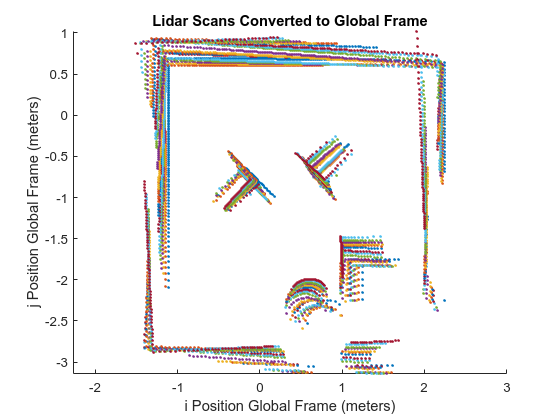

clf;
hold on;
axis equal;

% Load the scan data
load scandata.mat
position = scan_data(1:2,:);
heading = scan_data(3:4,:);
radius = scan_data(5:end,:);
theta = deg2rad([0:359]');
[x,y] = pol2cart(theta, radius);

for i = 1:size(position, 2)
    current_heading = heading(:,i)/norm(heading(:,i));
    [phi, ~] = cart2pol(current_heading(1), current_heading(2));
    current_i = x(:,i)';
    current_j = y(:,i)';
    scanned_points_neato = [current_i; current_j; ones(1,360)];

    T = [1 0 position(1, i);...
         0 1 position(2, i);...
         0 0 1];
    R = [cos(phi) -sin(phi) 0;...
         sin(phi) cos(phi)  0;...
         0        0         1];
    
    scanned_points_global = T * R * scanned_points_neato;
    plot(scanned_points_global(1,:), scanned_points_global(2,:), '.')
end

xlabel("i Position Global Frame (meters)")
ylabel("j Position Global Frame (meters)")
title("Lidar Scans Converted to Global Frame")

As you can see, the elements of the gauntlet are clearly visible, but it is not *quite* right. This is due to the error of where the robot actually is vs where the robot ***thinks*** it is increasing after every step. We recorded where the robot thoguht it was at the time of taking a scan. Thus, the points don't entirely line up.

**Potential Field:**

To create a map of the potential field, we created sources at each of the obstacles and a sink at the BoB. Additionally, every 0.01m of the walls, we created a source as well. As seen in the graph below, the contours point towards the sink for gradient descent without any unexpected valleys or hills on the path. The positions of the obstacles were: (-0.25, -1), (1, -0.7), (1.41, -2) and the position of the BoB was (0.75, -2.5). As seen below, cooler colors represent a lower contour level and warmer colors represent a higher level. Therefore, the BoB, which is a sink, has the coolest color.

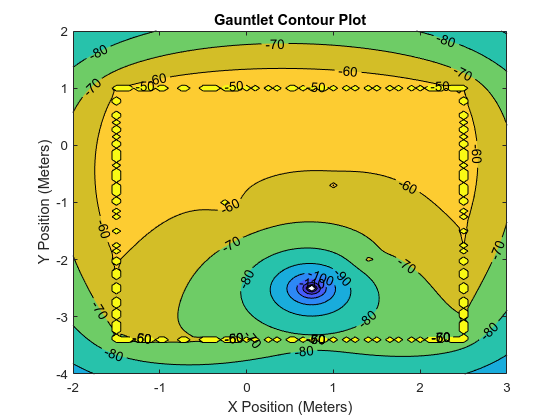

clf;

% Create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% Define barrel and obstacles
v = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.4*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2.5*log(sqrt((x-1.41).^2 + (y+2).^2));

% Define sources at lines for walls
for a = -1.5:0.01:2.5
    v = v - 0.05*log(sqrt((x-a).^2 + (y-1).^2));
    v = v - 0.05*log(sqrt((x-a).^2 + (y+3.4).^2));
end

for b = -3.37:0.01:1
    v = v - 0.05*log(sqrt((x+1.5).^2 + (y-b).^2));
    v = v - 0.05*log(sqrt((x-2.5).^2 + (y-b).^2));
end

% Draw contours
contourf(x, y, v, 'k', 'ShowText', 'On');
title('Gauntlet Contour Plot');
xlabel("X Position (Meters)")
ylabel("Y Position (Meters)")


$$\textrm{Equation}:\;V\left(x,y\right)=20*\ln \sqrt{{\left(x-0\ldotp 75\right)}^2 +{\left(y+2\ldotp 5\right)}^2 }-2*\ln \sqrt{{\left(x+0\ldotp 25\right)}^2 +{\left(y+1\right)}^2 }-2\ldotp 5*\ln \sqrt{{\left(x-1\ldotp 41\right)}^2 +{\left(y+2\right)}^2 }-0\ldotp 4*\ln \sqrt{{\left(x-1\right)}^2 +{\left(y+0\ldotp 7\right)}^2 }$$


For readability, the walls aren't included in this equation since we added sources every 0.5 meters along each wall. However, this is implemented through a for loop in our code. 

**Quiver Plot: **

For the quiver plot, we represented the same sources and sinks without scaling them up or down. All four walls can be seen on the graph as well as the sink for the BoB (the circle) and the three obstacles (the three darker spots on the main map).

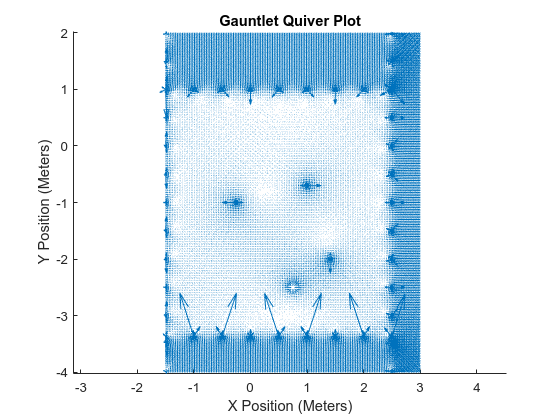

clf;
axis equal;
hold on;

% Create a meshgrid
[x,y]=meshgrid(-1.5:0.03:3,-4:0.03:2);

% Add sources (obstacles and BoB)
fx = ((x-0.75)./((x-0.75).^2+(y+2.5).^2)) - ((x+0.25)./((x+0.25).^2+(y+1).^2)) - ((x-1.41)./((x-1.41).^2+(y+2).^2)) - ((x-1)./((x-1).^2+(y+0.7).^2));
fy = ((y+2.5)./((x-0.75).^2+(y+2.5).^2)) - ((y+1)./((x+0.25).^2+(y+1).^2)) - ((y+2)./((x-1.41).^2+(y+2).^2)) - ((y+0.7)./((x-1).^2+(y+0.7).^2));

% Add walls
for a = -1.5:0.5:2.5
    fx = fx - ((x-a)./((x-a).^2 + (y-1).^2));
    fy = fy - ((y-1)./((x-a).^2 + (y-1).^2));

    fx = fx - ((x-a)./((x-a).^2 + (y+3.4).^2));
    fy = fy - ((y+3.37)./((x-a).^2 + (y+3.4).^2));
end

for b = -4:0.5:2
    fx = fx - ((x+1.5)./((x+1.5).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x+1.5).^2 + (y-b).^2));
 
    fx = fx - ((x-2.5)./((x-2.5).^2 + (y-b).^2));
    fy = fy - ((y-b)./((x-2.5).^2 + (y-b).^2));
end

% Plot
title("Gauntlet Quiver Plot");
xlabel("X Position (Meters)");
ylabel("Y Position (Meters)");
quiver(x,y,fx,fy,20)

**Gradient Descent Path (Expected):**

Finally, to predict the path of gradient descent, the gradient was found for the path and used to find the position of the Neato at each time step. These were plotted onto the contour map to ensure the Neato fould follow the predicted contours. 

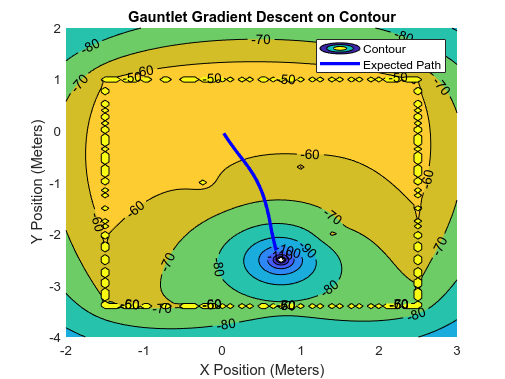

clf;
hold on;

% Get expected positions of Neato
final_positions = [];

wheelBase = 0.235;          
lambda = 0.01;

% Equation for contour
syms x y;
f = 20*(log(sqrt((x-0.75).^2 + (y + 2.5).^2))) - 2*log(sqrt((x+0.25).^2 + (y+1).^2)) - 0.4*log(sqrt((x-1).^2 + (y+0.7).^2)) - 2.5*log(sqrt((x-1.41).^2 + (y+2).^2));

% Find gradient of contour
grad = gradient(f, [x, y]);

% Initialize position
position = [0; 0];

% Gather 23 points
counter = 23;
while counter > 0
    % Get gradient for point
    gradValue = -1*double(subs(grad, {x, y}, {position(1), position(2)}));
    
    % Update the position for the next iteration
    position = position + (gradValue*lambda);
    final_positions = [final_positions position];
    counter = counter - 1;
end
 
% Create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% Draw contours
title("Gauntlet Gradient Descent on Contour")
xlabel("X Position (Meters)")
ylabel("Y Position (Meters)")
contourf(x, y, v, 'k', 'ShowText', 'On');

% Plot neato path expected
plot(final_positions(1, :), final_positions(2, :), 'b', 'LineWidth', 2.5)
legend("Contour", "Expected Path")

## Navigate Gauntlet

**Gradient Descent Path (Actual):**

Here is a graph of both the predicted (blue) and the actual (red) path taken by the Neato when beginning at [0, 0]. The actual data was calculated using encoder data, which is listed in 'encoders.csv'.

clf;
hold on;

% Wheelbase
d = .235;

% Load the simulated data from the encoders
encoder_table = readtable('encoders.csv');

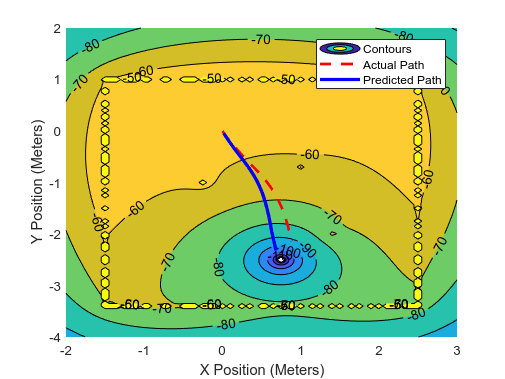

encoder = encoder_table{:,:};

% Manually looking at the file, movement does not appear to start until
% 77.4 seconds. This is the 105th entry.
encoder = encoder(105:size(encoder, 1), :);

% Normalize time to 0
encoder_time = encoder(:,1) - encoder(1,1);
encoder_l = encoder(:,2);
encoder_r = encoder(:,3);

% Calculate wheel velocities
encoder_v_l = diff(encoder_l) ./ diff(encoder_time);
encoder_v_r = diff(encoder_r) ./ diff(encoder_time);

encoder_v = (encoder_v_l + encoder_v_r) ./ 2;
encoder_omega = (encoder_v_r - encoder_v_l) ./ d;

position = [0; 0];
heading = [1; 0];
diff_encoder_time = diff(encoder_time);

num_vec = 7;
stop_gaps = round(length(encoder_v) / num_vec);
current_vec = 1;

for i = 1:length(diff_encoder_time)
    position(:,i+1) = position(:,i) + (heading(:,i) .* encoder_v(i) .* diff_encoder_time(i));
    % Rotate the heading
    theta = encoder_omega(i) * diff_encoder_time(i);
    R = [cos(theta), -sin(theta);
         sin(theta), cos(theta)];
    heading(:, i+1) = R * heading(:,i);

    % Print the tangent vectors
    if mod(i, stop_gaps) == 0
        pos_actual(:,current_vec) = [position(1, i); position(2, i)];
        head_actual(:,current_vec) = [heading(1, i), heading(2, i)];
        current_vec = current_vec + 1;
    end
end

xlabel("X Position (Meters)")
ylabel("Y Position (Meters)")

% Create a meshgrid
[x,y]=meshgrid(-2:0.05:3,-4:0.05:2);

% Draw contours
contourf(x, y, v, 'k', 'ShowText', 'On');
% Plot measured trajectory
plot(position(1,:), position(2,:), 'r--', 'LineWidth', 2.0)
plot(final_positions(1, :), final_positions(2, :), 'b', 'LineWidth', 2.5) % expected
legend("Contours", "Actual Path", "Predicted Path")

% Find distance actually travelled
x_deltas = diff(position(1,:));
y_deltas = diff(position(2,:));
step_sizes = sqrt(x_deltas.^2 + y_deltas.^2);
distance = sum(step_sizes)

distance = 2.3397

It took the Neato about 20.1 seconds to travel a distance of 2.3397 meters. This isn't very accurate to the predicted path. One reason for this is that, as seen in the LIDAR graph above, the Neato's estimation of it's current position in qeasim is inaccurate, which causes it to alter from the expected path it would take. However, this is still accurate enough to reach the BoB.